# Parameters


clear all; close all;
N=9;
M=20;
hn=zeros(1,N);
hnew=zeros(M,N);
a1=4;
xn=2*a1*(rand(1,M)-0.5)

xn =     1.2202    3.3384    0.0787    3.7935   -2.4218   -3.1105   -1.6212   -0.8287   -0.6340   -1.5082    1.5507   -3.2650   -0.7833   -1.6386   -1.5480   -3.1555    0.7506   -1.7382   -2.7582   -3.9947


xb=fir1(N-1,0.5);
xa=[1 1 1]

xa =      1     1     1


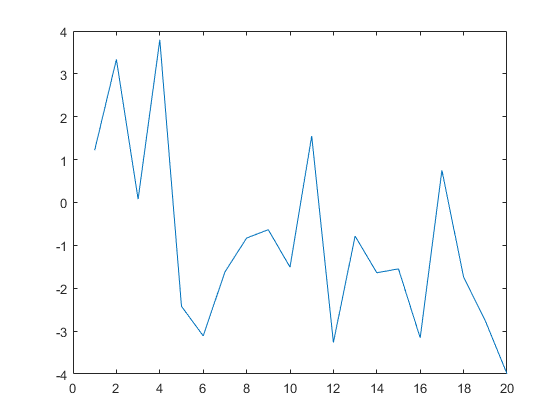

dn=filter(xb,1,xn);
plot(xn)

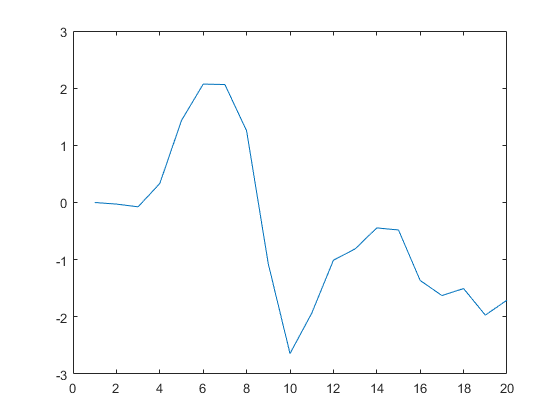

plot(dn)

Px=(1/length(xn))*sum(xn.^2);


## caclculate new h:

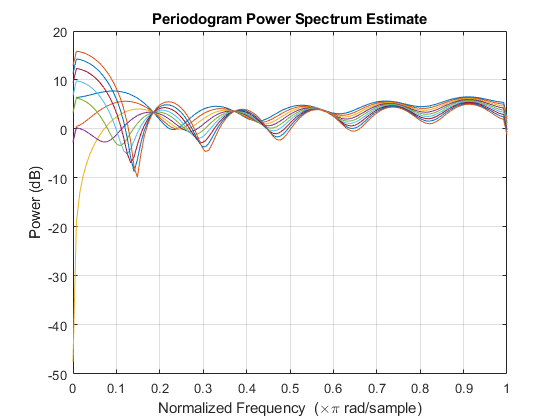


delta=1/(9*N*Px);
k=1;
for n=N:M
    xn_k=(n:-1:n-N+1);
    yn(n)=xn_k*hn';
    en(n)=dn(n)-yn(n);
    hn=hn+delta*(xn_k*en(n));
    hnew(k,:)=hn;
    k=k+1;
end
periodogram(hnew,'power')